Se implementaron algunas ventanas, que se tendrán disponibles en el cálculo del espectrograma. Estas ventanas son 

- Hanning

- Blackman

- Hamming

- Hann

- Kaiser

#### Prueba ventanas 

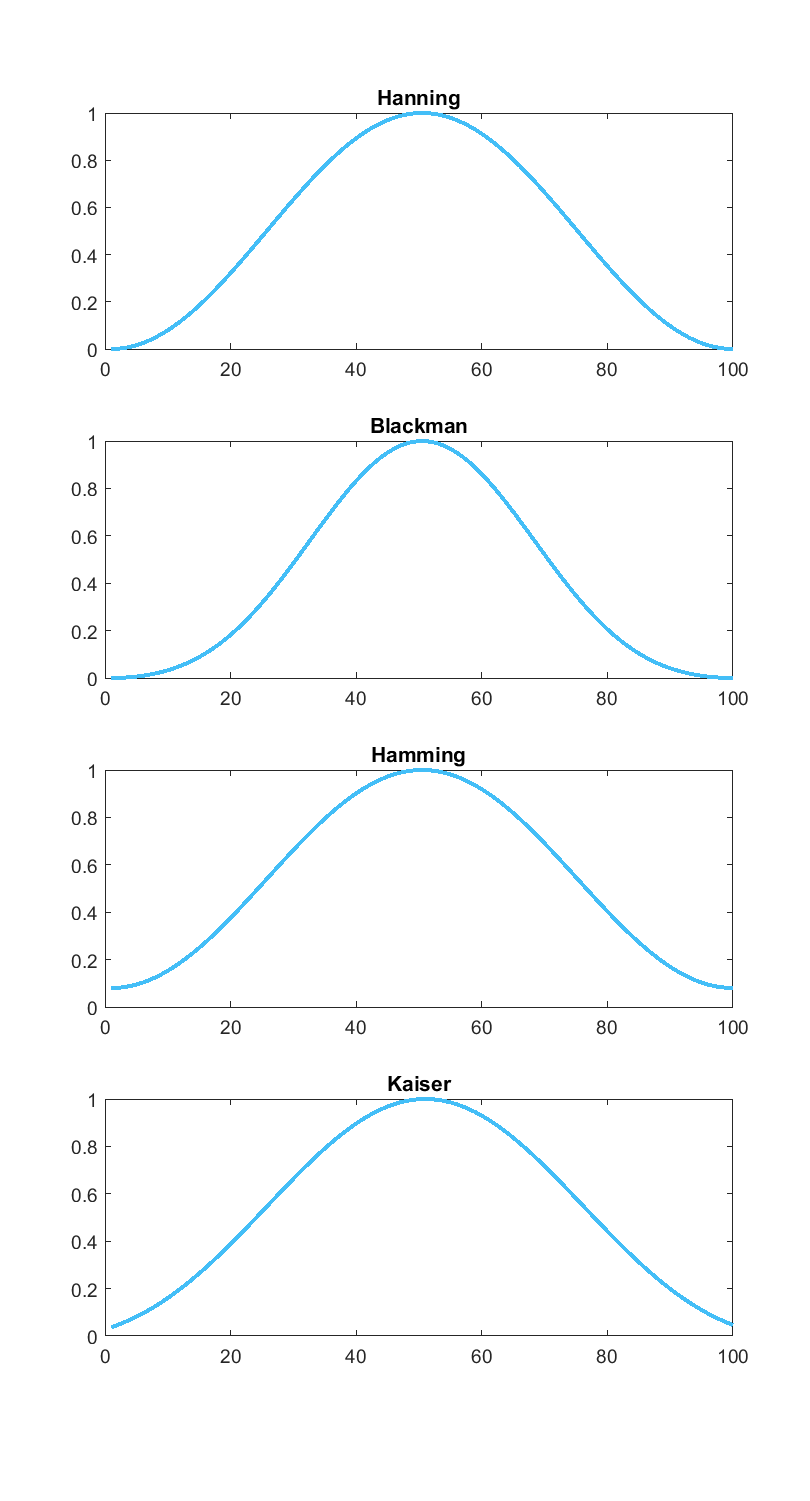

N = 100;
windowCalculator = WindowCalculator();
%Ventana Hanning
hannWindow = windowCalculator.getWindow(WindowType.HANNING, N);
%Ventana Blackman
blackmanWindow = windowCalculator.getWindow(WindowType.BLACKMAN, N);
%Ventana Hamming
hammingWindow = windowCalculator.getWindow(WindowType.HAMMING, N);
%Ventana Kaiser
kaiserWindow = windowCalculator.getWindow(WindowType.KAISER, N);


f = figure;
f.Position = [100 100 540 1000];
subplot(4,1,1)
plot(1:N, hannWindow, "Color", "#43bef7", "LineWidth", 2)
title("Hanning")
subplot(4,1,2)
plot(1:N, blackmanWindow, "Color", "#43bef7", "LineWidth", 2)
title("Blackman")
subplot(4,1,3)
plot(1:N, hammingWindow, "Color", "#43bef7", "LineWidth", 2)
title("Hamming")
subplot(4,1,4)
plot(1:N, kaiserWindow, "Color", "#43bef7", "LineWidth", 2)
title("Kaiser")

### Prueba SDFT

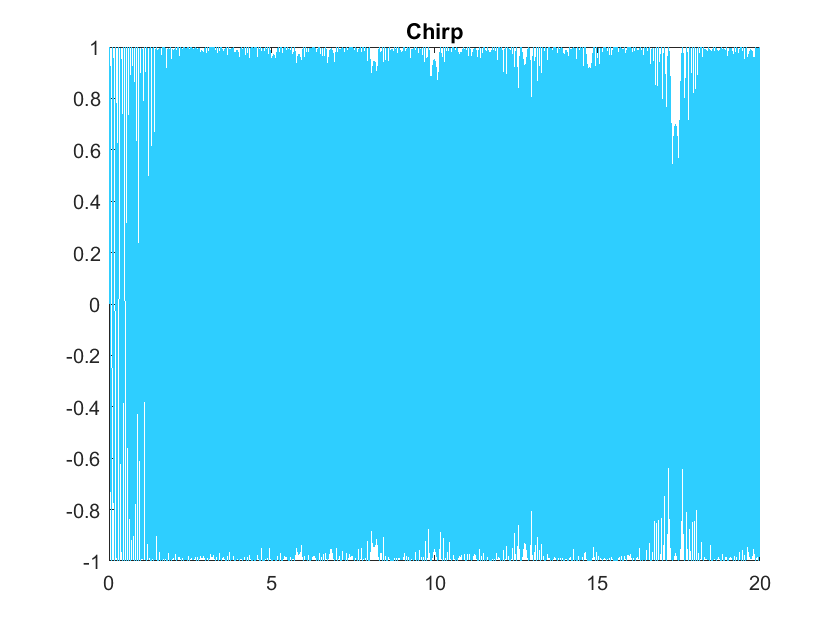

%Probemos con una chirp
initialFrequency = 10;
finalFrequency = 100;
endTime = 20;
nPoints = 10000;
tArray = linspace(0,endTime,nPoints);
signal = sin(2*pi*(initialFrequency + ((finalFrequency - initialFrequency)/endTime).*tArray).*tArray);

figure()
plot(tArray, signal, "Color", "#2eceff")
title("Chirp")

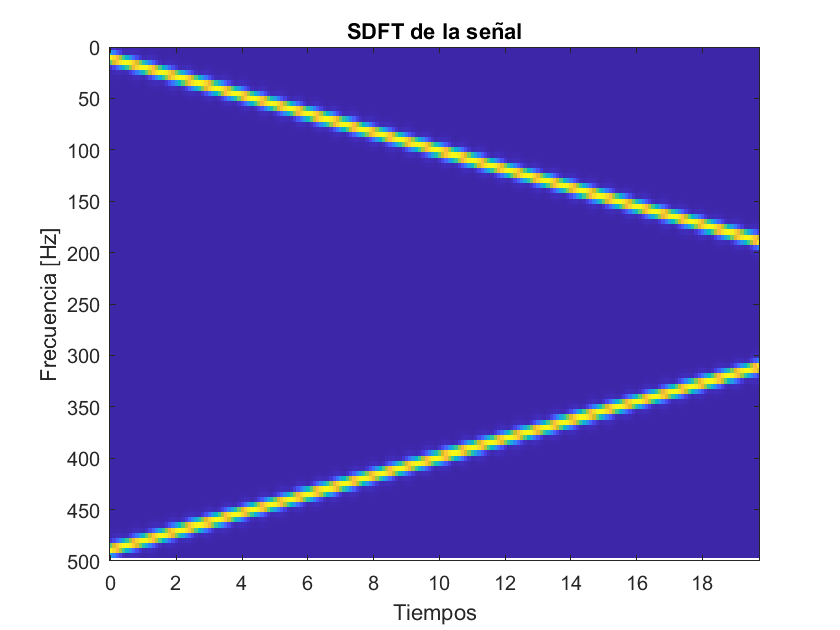

sdftCalculator = SDFTCalculator();
overlap = 0.5;
windowType = WindowType.HANNING;
windowPoints = 100;

[times, freqs, sdft] = sdftCalculator.computeSDFT(signal,tArray,windowType, windowPoints, overlap);

figure()
imagesc(times, freqs, abs(sdft))
title("SDFT de la señal")
xlabel("Tiempos")
ylabel("Frecuencia [Hz]")
ylim([0,500])

### **Prueba SpectrogramPlotter**

windowPoints = 200;
overlap = 0.5;

spectrogramPlotter = SpectrogramPlotter(WindowType.HANNING, windowPoints, overlap);

spectrogramPlotter.plotMagnitudeSpectrogram(signal, tArray);

Descripción 
-----------------
Tipo de ventana: HANNING
Puntos en la ventana: 200
Porcentaje de traslape: 0.5



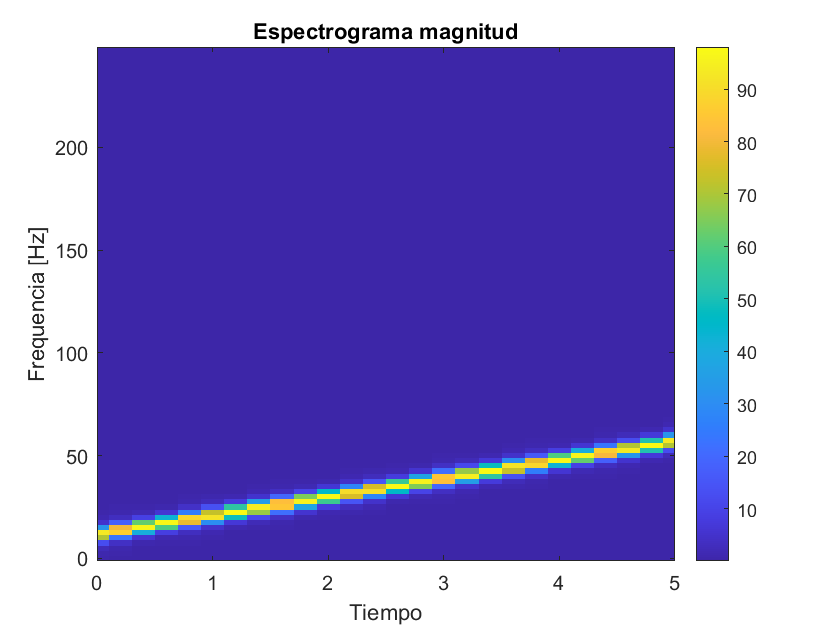

xlim([0,5])

Descripción 
-----------------
Tipo de ventana: HANNING
Puntos en la ventana: 200
Porcentaje de traslape: 0.5



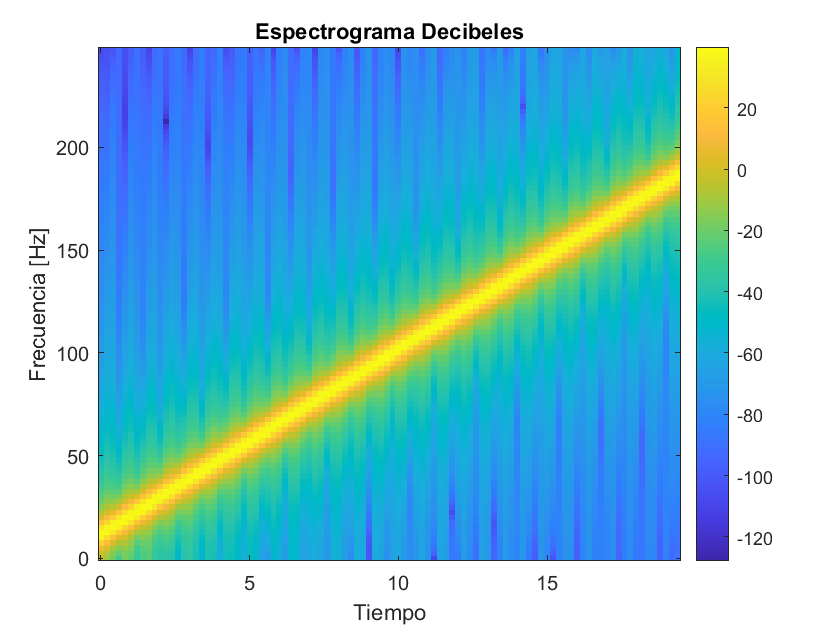

spectrogramPlotter.plotDecibelSpectrogram(signal, tArray);

### Prueba con una mini canción grabada en 2 escalas distintas. 

### Primera canción

%Leemos el audio 
[firstSong, Fs] = audioread('converted_hk_1.wav', 'native');
disp("Sampling frequency "+string(Fs))

Sampling frequency 8000


%Vamos a reproducirla 
soundsc(double(firstSong), Fs);

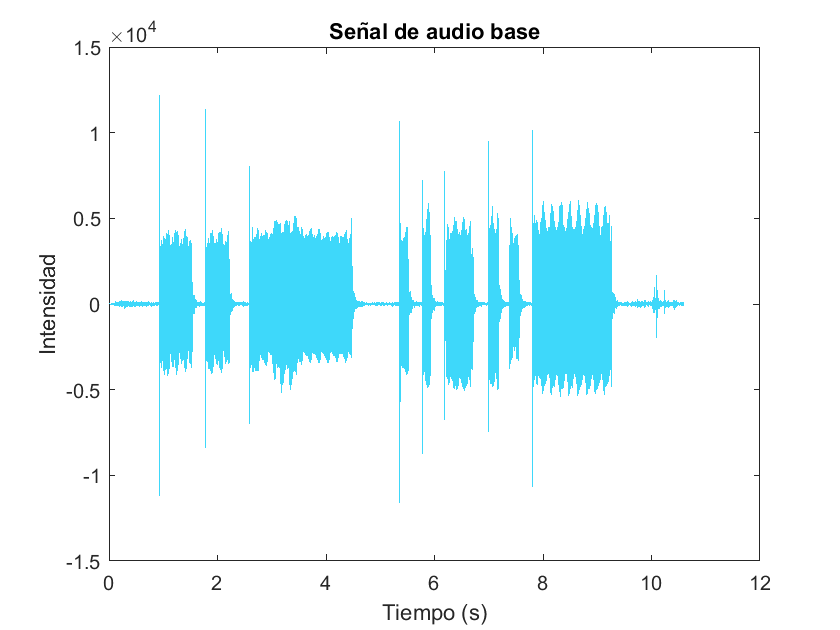

deltaT = 1/Fs;
n = size(firstSong, 1);
tArray = (0:1:n-1)*deltaT;

figure()
plot(tArray, firstSong, "Color", "#3ed8fa")
title("Señal de audio base")
xlabel("Tiempo (s)")
ylabel("Intensidad")

Descripción 
-----------------
Tipo de ventana: HANNING
Puntos en la ventana: 500
Porcentaje de traslape: 0.5



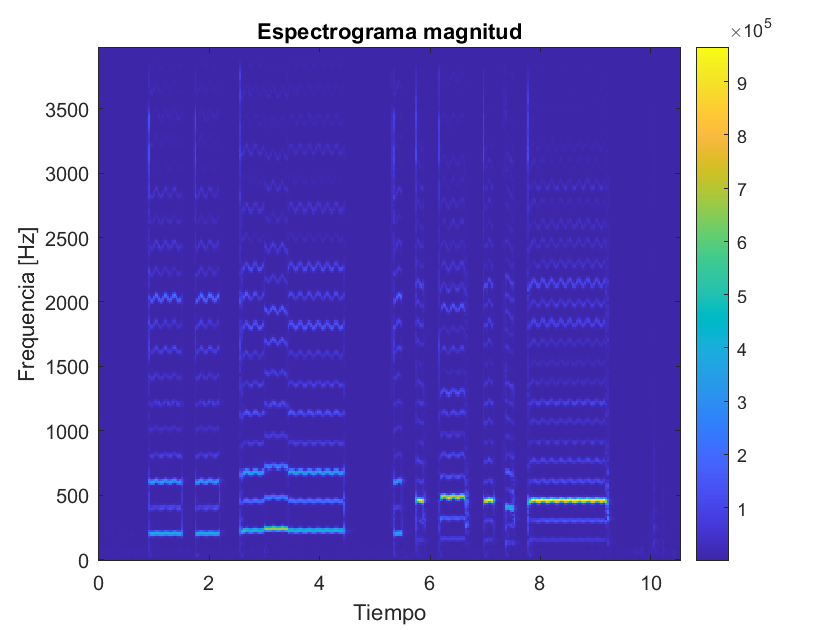

windowPoints = 500;
overlap = 0.5;

spectrogramPlotter = SpectrogramPlotter(WindowType.HANNING, windowPoints, overlap);
spectrogramPlotter.plotMagnitudeSpectrogram(double(firstSong'), tArray);

  266.6667



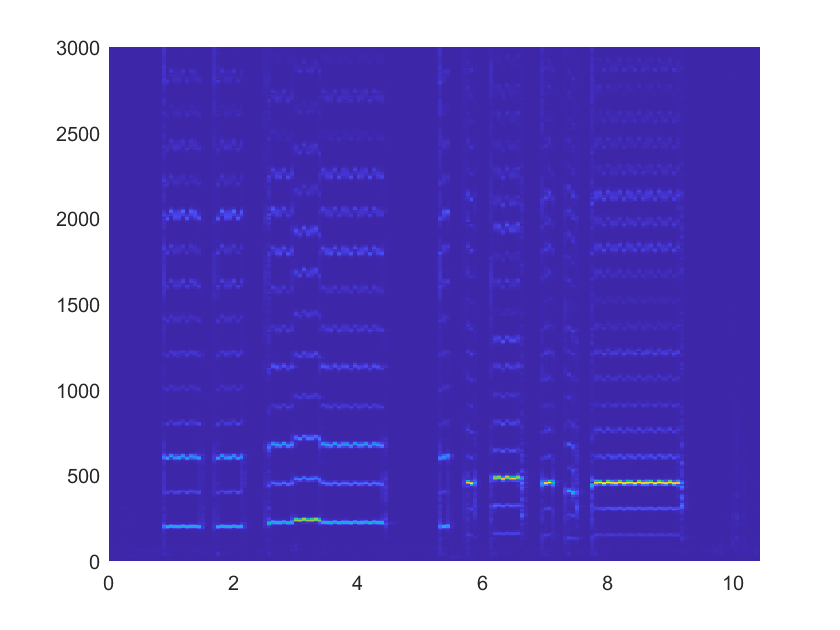

fps = 30;
fMin = 0;
fMax = 3000;
audioSpectrogramAnimator = AudioSpectrogramAnimator(WindowType.HANNING, 1000, 0.5);
audioSpectrogramAnimator.animateAudioSpectrogram(Fs,double(firstSong'),firstSong, fps, 'first_song.avi', fMin, fMax);

### Segunda canción

[secondSong, Fs] = audioread("converted_hk_2.wav", 'native');

soundsc(double(secondSong), Fs);

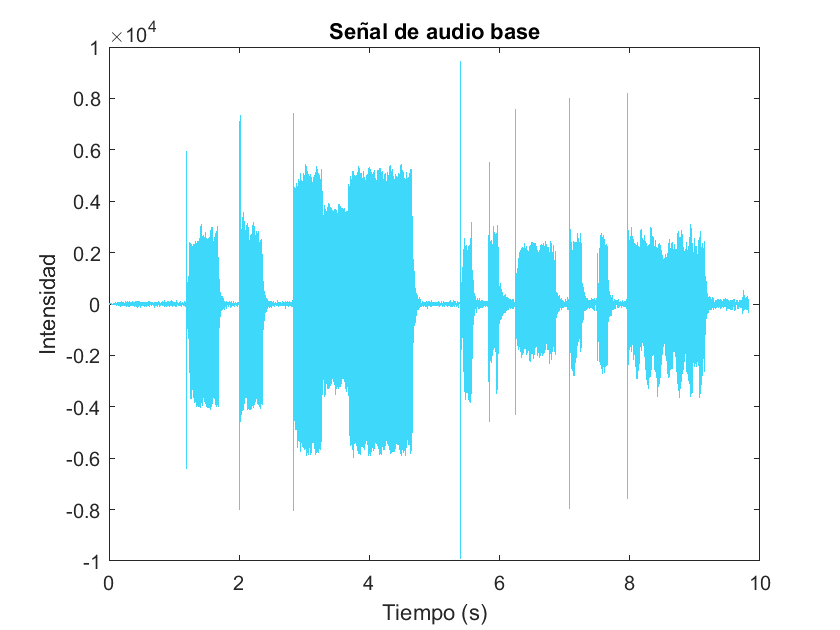

deltaT = 1/Fs;
n = size(secondSong, 1);
tArray = (0:1:n-1)*deltaT;

figure()
plot(tArray, double(secondSong), "Color", "#3ed8fa")
title("Señal de audio base")
xlabel("Tiempo (s)")
ylabel("Intensidad")

windowPoints = 500;
overlap = 0.5;

spectrogramPlotter = SpectrogramPlotter(WindowType.HANNING, windowPoints, overlap);
spectrogramPlotter.plotMagnitudeSpectrogram(double(secondSong)', tArray);

Descripción 
-----------------
Tipo de ventana: HANNING
Puntos en la ventana: 500
Porcentaje de traslape: 0.5



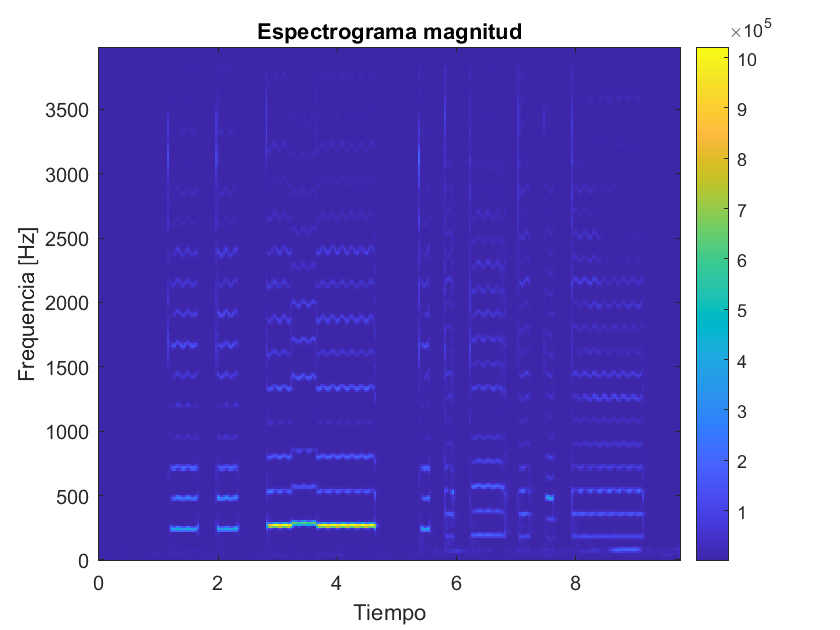

  266.6667



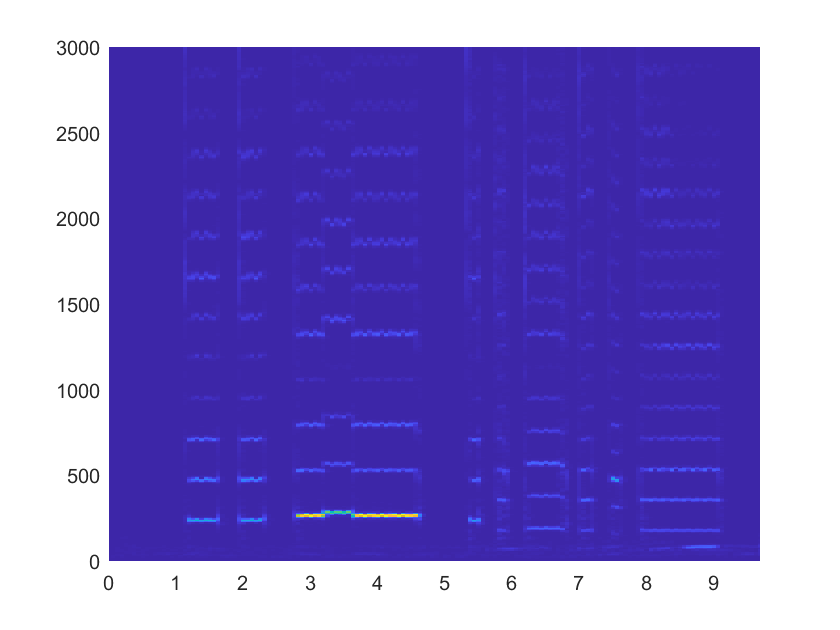

fps = 30;
fMin = 0;
fMax = 3000;
audioSpectrogramAnimator = AudioSpectrogramAnimator(WindowType.HANNING, 1000, 0.5);
audioSpectrogramAnimator.animateAudioSpectrogram(Fs,double(secondSong'),secondSong, fps, 'second_song.avi', fMin, fMax);

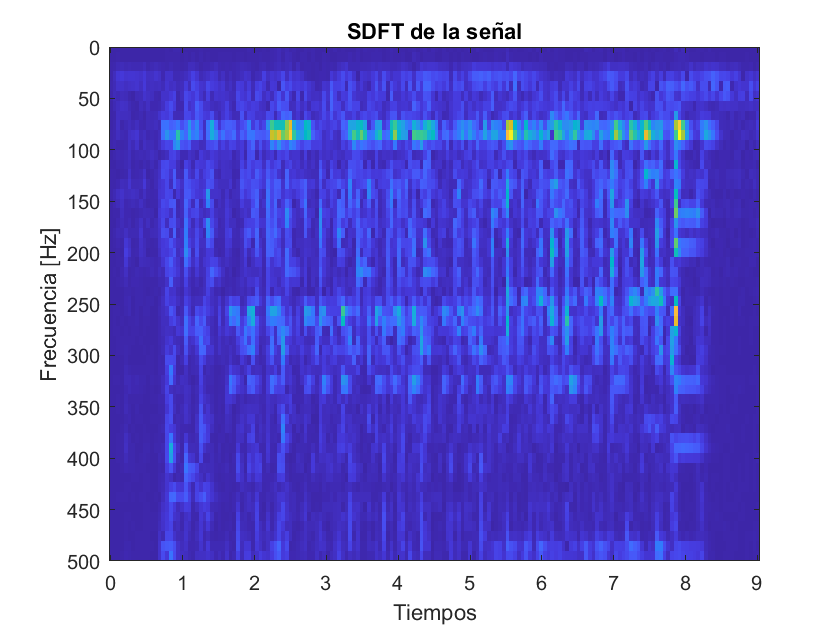

sdftCalculator = SDFTCalculator();
overlap = 0.5;
windowType = WindowType.HANNING;
windowPoints = 5000;

[times, freqs, sdft] = sdftCalculator.computeSDFT(signal',tArray,windowType, windowPoints, overlap);

figure()
imagesc(times, freqs, abs(sdft))
title("SDFT de la señal")
xlabel("Tiempos")
ylabel("Frecuencia [Hz]")
ylim([0,500])